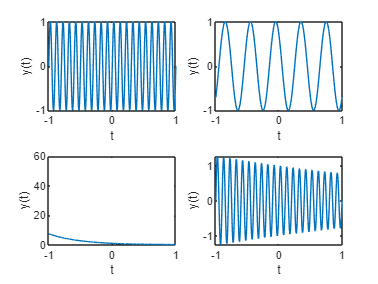

a=1+mod(111,3);
t=-1:0.001:1;
y1=sin(20*pi*a*t);
subplot(2,2,1)
plot(t,y1)
y2=cos(5*pi*a*t+(pi/4));
subplot(2,2,2)
plot(t,y2)
y3=exp(-2*a*t);
subplot(2,2,3)
plot(t,y3)
y4=exp(-0.25*a*t).*(sin(20*pi*t));
subplot(2,2,4)
plot(t,y4)

subplot(2,2,1)
xlabel("t")

subplot(2,2,2)
ylabel("y(t)")
subplot(2,2,4)

subplot(2,2,1)

subplot(2,2,2)
xlabel("t")

subplot(2,2,1)
ylabel("y(t)")

subplot(2,2,3)
xlim([-1.00 1.00])
ylim([0 60])
xlabel("t")
ylabel("y(t)")
subplot(2,2,4)
xlabel("t")
ylabel("y(t)")

a=1+mod(111,3);
t=-5:0.001:5;
x=exp(-a*t)

x =   148.4132  148.2648  148.1166  147.9686  147.8207  147.6729  147.5253  147.3779  147.2306  147.0834  146.9364  146.7896  146.6428  146.4963  146.3499  146.2036  146.0574  145.9115  145.7656  145.6199  145.4744  145.3290  145.1837  145.0386  144.8936  144.7488  144.6041  144.4596  144.3152  144.1710  144.0269  143.8829  143.7391  143.5955  143.4519  143.3086  143.1653  143.0222  142.8793  142.7365  142.5938  142.4513  142.3089  142.1667  142.0246  141.8826  141.7408  141.5991  141.4576  141.3162


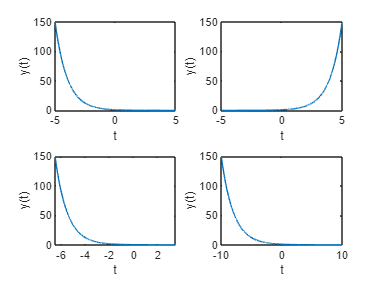

subplot(2,2,1)
plot(t,x)
subplot(2,2,2)
plot(-t,x)
subplot(2,2,3)
plot(t-(1.5*a),x)
subplot(2,2,4)
plot(2*a*t,x)

subplot(2,2,1)
xlabel("t")
ylabel("y(t)")
subplot(2,2,2)
xlabel("t")
ylabel("y(t)")
subplot(2,2,3)
xlabel("t")
ylabel("y(t)")
subplot(2,2,4)
xlabel("t")
ylabel("y(t)")

ecg=load("ECG_Data.txt")

ecg =     0.2284
    0.2240
    0.2206
    0.2163
    0.2111
    0.2059
    0.1998
    0.1964
    0.1938
    0.1886


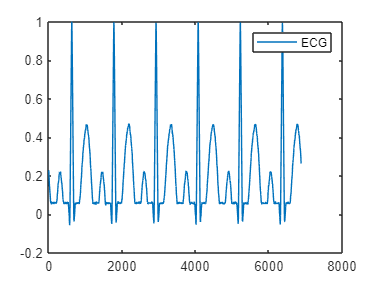

subplot(1,1,1)
plot(ecg)

legend("ECG")

jan_rain=load("RainFallIndia_Jan.txt")

jan_rain =   107.3000
   43.7000
   32.7000
   42.2000
   33.3000
   28.0000
   42.2000
   42.2000
   83.7000
   70.3000


nbins=5

nbins = 5

histogram(jan_rain,nbins)
hold on
july_rain=load("RainFallIndia_July.txt")

july_rain = 1.0e+03 *

    0.2850
    0.4213
    0.4654
    0.6601
    0.9909
    0.2174
    0.8519
    0.6601
    0.2720
    0.4608


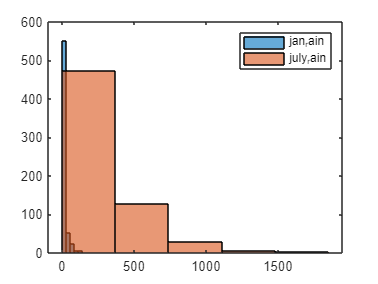

histogram(july_rain,nbins)
hold off

legend("show")

m=[jan_rain;july_rain]

m = 1.0e+03 *

    0.1073
    0.0437
    0.0327
    0.0422
    0.0333
    0.0280
    0.0422
    0.0422
    0.0837
    0.0703


mean(m)

ans = 172.2224

std(m)

ans = 220.0828

[y,Fs]=audioread("Track001.wav")

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 44100

sound(y,Fs)

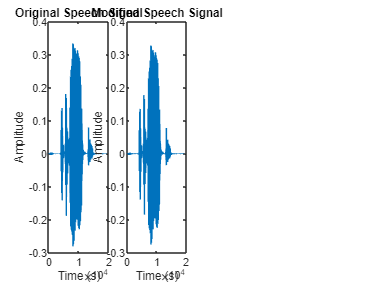

% Load the speech signal from the WAV file
[s, fs] = audioread('speech.wav');


% Plot the original speech signal
t = 0:0.0005:1;
subplot(1, 4, 1);
plot(s);
title('Original Speech Signal');
xlabel('Time (s)');
ylabel('Amplitude');
F = 500;
y = s.* cos((2 * pi * F ) / fs);
subplot(1, 4, 2);
plot(y);
title('Modified Speech Signal');
xlabel('Time (s)');
ylabel('Amplitude');



% f1=fft(s)
% subplot(2, 2, 3);
% title('fourier transform of original signal');
% xlabel('Time (s)');
% ylabel('Amplitude');
% plot(t,f1)

f1=fft(s)

f1 = 1.0e+02 *

   0.3704 + 0.0000i
  -0.2912 - 0.0933i
   0.1662 + 0.0740i
  -0.1196 - 0.0416i
   0.0800 + 0.0614i
   0.0022 - 0.0479i
  -0.0223 - 0.0201i
  -0.0280 + 0.0329i
   0.0421 + 0.0178i
  -0.0045 - 0.0350i


N=length(f1)

N = 19120

f_axis=linspace(0,Fs,N)

f_axis = 1.0e+04 *

         0    0.0002    0.0005    0.0007    0.0009    0.0012    0.0014    0.0016    0.0018    0.0021    0.0023    0.0025    0.0028    0.0030    0.0032    0.0035    0.0037    0.0039    0.0042    0.0044    0.0046    0.0048    0.0051    0.0053    0.0055    0.0058    0.0060    0.0062    0.0065    0.0067    0.0069    0.0072    0.0074    0.0076    0.0078    0.0081    0.0083    0.0085    0.0088    0.0090    0.0092    0.0095    0.0097    0.0099    0.0101    0.0104    0.0106    0.0108    0.0111    0.0113


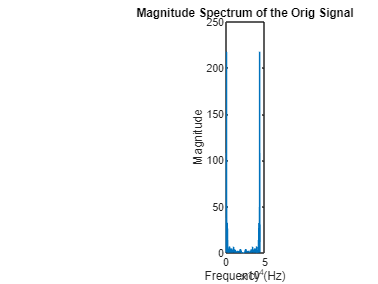

figure;
subplot(1,4,3)
plot(f_axis,abs(f1))
title('Magnitude Spectrum of the Orig Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');


f2=fft(y)

f2 = 1.0e+02 *

   0.3632 + 0.0000i
  -0.2856 - 0.0915i
   0.1630 + 0.0725i
  -0.1173 - 0.0408i
   0.0785 + 0.0602i
   0.0022 - 0.0470i
  -0.0219 - 0.0197i
  -0.0275 + 0.0323i
   0.0413 + 0.0175i
  -0.0044 - 0.0344i


N=length(f1)

N = 19120

f_axis=linspace(0,Fs,N)

f_axis = 1.0e+04 *

         0    0.0002    0.0005    0.0007    0.0009    0.0012    0.0014    0.0016    0.0018    0.0021    0.0023    0.0025    0.0028    0.0030    0.0032    0.0035    0.0037    0.0039    0.0042    0.0044    0.0046    0.0048    0.0051    0.0053    0.0055    0.0058    0.0060    0.0062    0.0065    0.0067    0.0069    0.0072    0.0074    0.0076    0.0078    0.0081    0.0083    0.0085    0.0088    0.0090    0.0092    0.0095    0.0097    0.0099    0.0101    0.0104    0.0106    0.0108    0.0111    0.0113


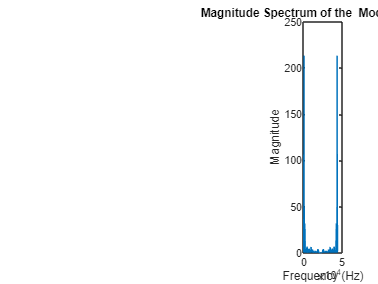

figure;
subplot(1,4,4)
plot(f_axis,abs(f2))
title('Magnitude Spectrum of the  Modified Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

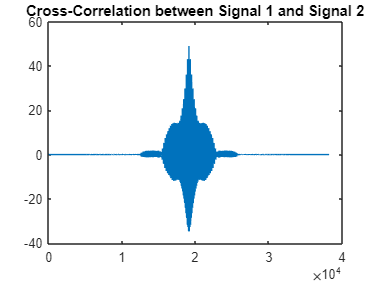




% subplot(2, 2, 4);
% title('fourier transform of modified signal');
% xlabel('Time (s)');
% ylabel('Amplitude');
% plot(t,f2)

% Calculate cross-correlation
corr = xcorr(s,y);

% Plot cross-correlation
figure;
plot(corr);
title('Cross-Correlation between Signal 1 and Signal 2');



% sound(s,fs)

sound(y,fs)

fs = 5000; % Sampling frequency in Hz (time resolution of 0.001s)
t = 0:0.001:4.999; % Time vector from 0 to 4.999 seconds

% Frequency values
alpha = 2.0; % Adjust as needed
f1 = 200 * alpha; % Frequency of the first sinusoid (200α Hz)
f2 = 220 * alpha; % Frequency of the second sinusoid (220α Hz)

% Generate the sinusoids
sinusoid1 = sin(2 * pi * f1 * t);
sinusoid2 = sin(2 * pi * f2 * t);

% Combine the sinusoids
combined_signal = sinusoid1 + sinusoid2;

% Normalize the signal to the range [-1, 1]
combined_signal = combined_signal / max(abs(combined_signal));

% Write the combined signal ++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++to a .wav file
audiowrite('combined_sinusoids.wav', combined_signal, fs);

% Listen to the combined signal
sound(combined_signal, fs);

fs = 44100; % Sampling frequency in Hz
t = 0:1/fs:1.5; % Time vector for each note (1.5 seconds per note)

% Frequencies for each note (Do, Re, Mi, Fa, So, La, Ti, Do)
frequencies = [261.63, 293.66, 329.63, 349.23, 392.00, 440.00, 493.88, 523.25];

% Initialize an empty signal
combined_signal = zeros(1, length(t) * length(frequencies));

% Generate and append the sinusoidal signals for each note
for i = 1:length(frequencies)
    note_signal = sin(2 * pi * frequencies(i) * t);
    combined_signal(1, (i - 1) * length(t) + 1 : i * length(t)) = note_signal;
end

% Normalize the signal to the range [-1, 1]
combined_signal = combined_signal / max(abs(combined_signal));

% Write the combined signal to a .wav file
audiowrite('melody_sequence.wav', combined_signal, fs);
sound(combined_signal, fs);

textData=load("ConvFile1.txt")

textData =    -0.0000
    0.0000
    0.0001
    0.0001
    0.0002
    0.0002
    0.0003
    0.0003
    0.0003
    0.0003


[y,Fs]=audioread('Track001.wav')

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 44100

% sound(y,Fs)
normalizedText = textData / max(abs(textData));
convolution_result = conv(y,normalizedText);


audiowrite('convolution_result.wav', convolution_result, fs);

[soun,Fs]=audioread('convolution_result.wav')

soun =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 44100

sound(soun,Fs)




